## MATLAB大作业

clear; clc;
format long

## 第一部分：数据导入与可视化

path_users = './data/Foursquare/users.csv';
path_tips = './data/Foursquare/tips.csv';
path_friends = './data/Foursquare/friends.csv';
path_country = './data/COVID19/country.csv';
path_daily = './data/COVID19/daily_info.csv';
% users = readtable(path_users); tips = readtable(path_tips); friends = readtable(path_friends);
% country = readtable(path_country); daily = readtable(path_country)

SA = StatisticsAnalysis( ...
    'TablePath', path_daily, ...
    'ImportOptions', { ...
        'VariableTypes', { ...
            'new_vaccinations', 'double';
            'total_vaccinations', 'double' ...
            }; ...
        'SelectedVariableNames', {'date', 'new_cases', 'new_vaccinations'}; ...
        'DataLines', [4850, Inf] ...
        }, ...
    'SelectTableOptions', { ...
        'location', 'France'; ... Country
        'date', { ...
            arange(["2020-01-01", "2020-12-31"], 'openright'); ...
            arange(["2021-04-01", "2022-04-01"], 'openright') ...
            } ... Time Range
        }, ... % Will Automatically Select Table Before Importing Table
     'TagsGenerateOptions', { ...
        'CustomTagName', {'sexy', [0 1 1]; 'dance', [1 0 0]}; ...
        'TagContinuity', [0 1 1]; ...
        'CustomTagFunction', { ...
            'sexy', 'SexyVariance', @(x,y)tsnanvar(x{:,:})/2; ...
            'dance', 'DancingRatio', @(x,y)'p' ...
            } ...
        }...
    )

SA =   StatisticsAnalysis with properties:

                     Tags: [16×3 table]
                    Table: [680×3 table]
                TablePath: './data/COVID19/daily_info.csv'
            ImportOptions: {2×2 cell}
    detectedImportOptions: [1×1 matlab.io.text.DelimitedTextImportOptions]

SA.Table.Properties

ans =   TableProperties with properties:
               Description: ''
                  UserData: []
            DimensionNames: {'Row'  'Variables'}
             VariableNames: {'date'  'new_cases'  'new_vaccinations'}
      VariableDescriptions: {}
             VariableUnits: {}
        VariableContinuity: []
                  RowNames: {}
   Custom Properties (access using t.Properties.CustomProperties.<name>):
     detectedImportOptions: [1×1 matlab.io.text.DelimitedTextImportOptions]
                      Tags: [16×3 table]
                      Size: [680 3]
                  TagNames: {{2×1 cell}  {2×1 cell}  {2×1 cell}}
               UniqueCount: {[680]  [655]  [368]}
                ValueClass: {'datetime'  'double'  'double'}
              MissingCount: {[0]  [10]  [312]}
              MissingRatio: {[0]  [0.014705882352941]  [0.458823529411765]}
    LogicalRatioFirstValue: {[]  []  []}


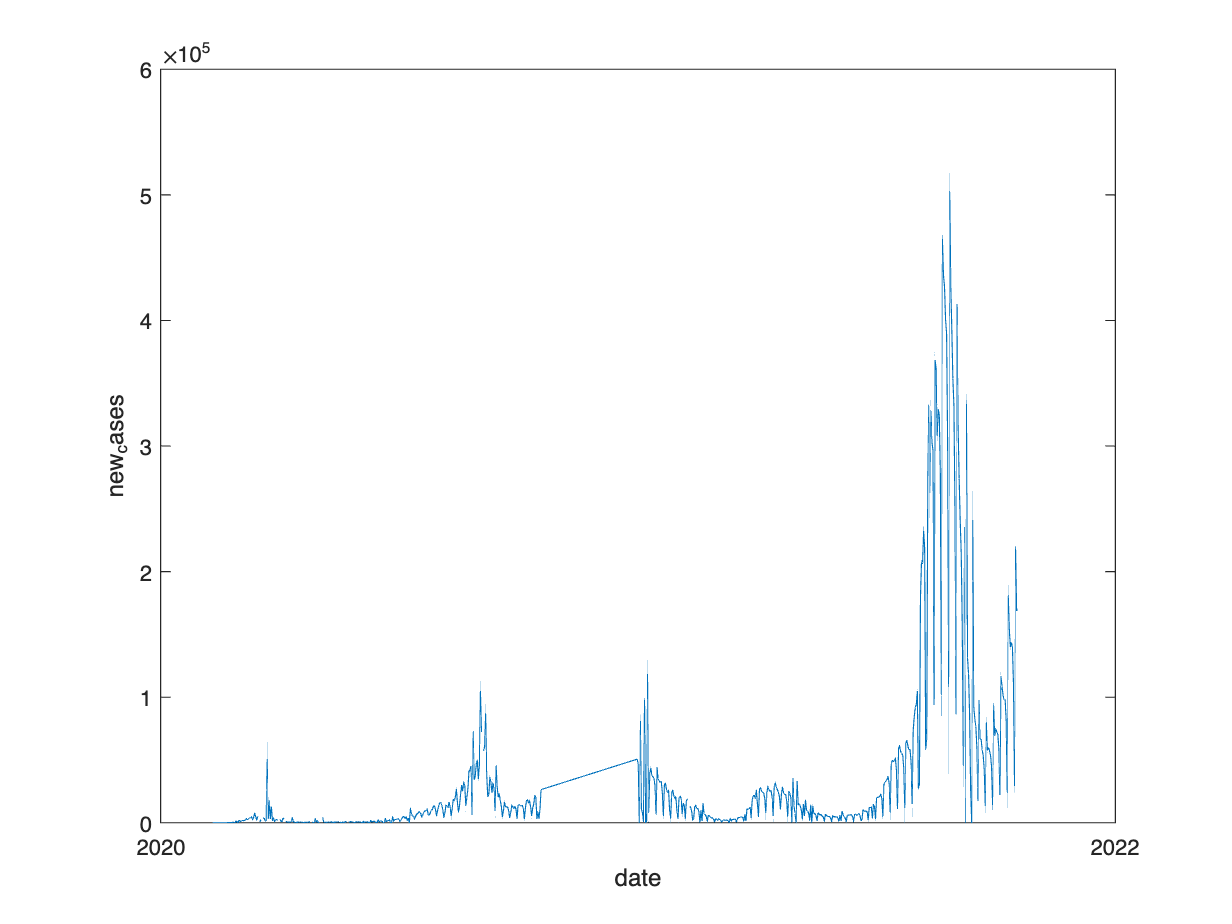

daily = table2timetable(SA.Table);
figure(1); plot(daily, 'new_cases'); datetick x;

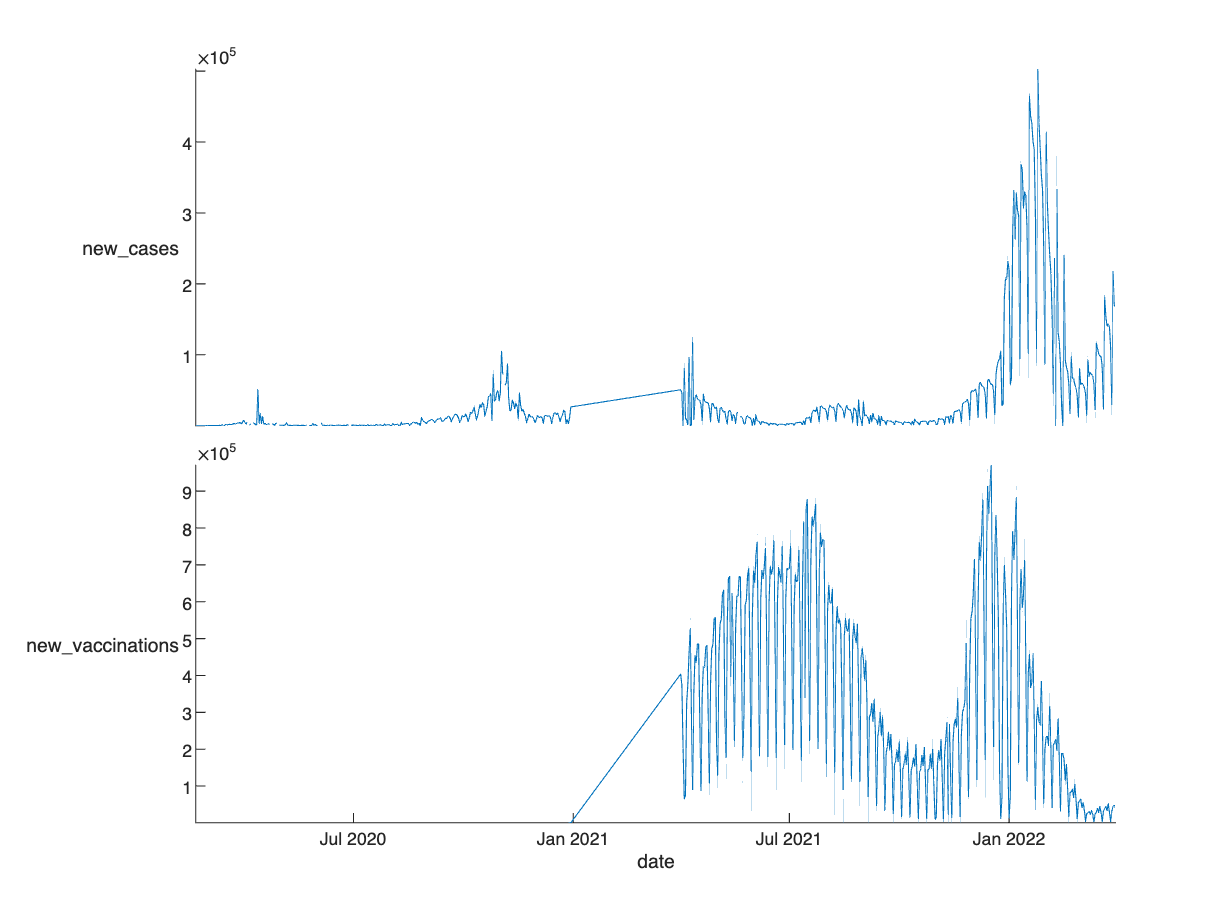

figure(2); stackedplot(daily);

daily.Properties

ans =   TimetableProperties with properties:
               Description: ''
                  UserData: []
            DimensionNames: {'date'  'Variables'}
             VariableNames: {'new_cases'  'new_vaccinations'}
      VariableDescriptions: {}
             VariableUnits: {}
        VariableContinuity: []
                  RowTimes: [680×1 datetime]
                 StartTime: 2020-02-20
                SampleRate: NaN
                  TimeStep: NaN
   Custom Properties (access using t.Properties.CustomProperties.<name>):
     detectedImportOptions: [1×1 matlab.io.text.DelimitedTextImportOptions]
                      Tags: [16×3 table]
                      Size: [680 3]
                  TagNames: {{2×1 cell}  {2×1 cell}}
               UniqueCount: {[655]  [368]}
                ValueClass: {'double'  'double'}
              MissingCount: {[10]  [312]}
              MissingRatio: {[0.014

## 第二部分：缺失值处理

path_daily = './data/COVID19/daily_info.csv';
SA = StatisticsAnalysis( ...
    'TablePath', path_daily, ...
    'ImportOptions', { ...
        'VariableTypes', { ...
            'new_vaccinations', 'double';
            'total_vaccinations', 'double' ...
            }; ...
        'SelectedVariableNames', {'date', 'new_cases', 'total_cases'} ...
        }, ...
    'SelectTableOptions', { ...
        'location', 'France'; ... Country
        'date', { ...
            arange(["2020-01-01", "2020-12-31"], 'closed')
            } ... Time Range
        } ... % Will Automatically Select Table Before Importing Table
    ).TagsGenerate;
data = SA.addProp;

MissingMap = data.Properties.CustomProperties.MissingMap;
% 缺失值处理
% 

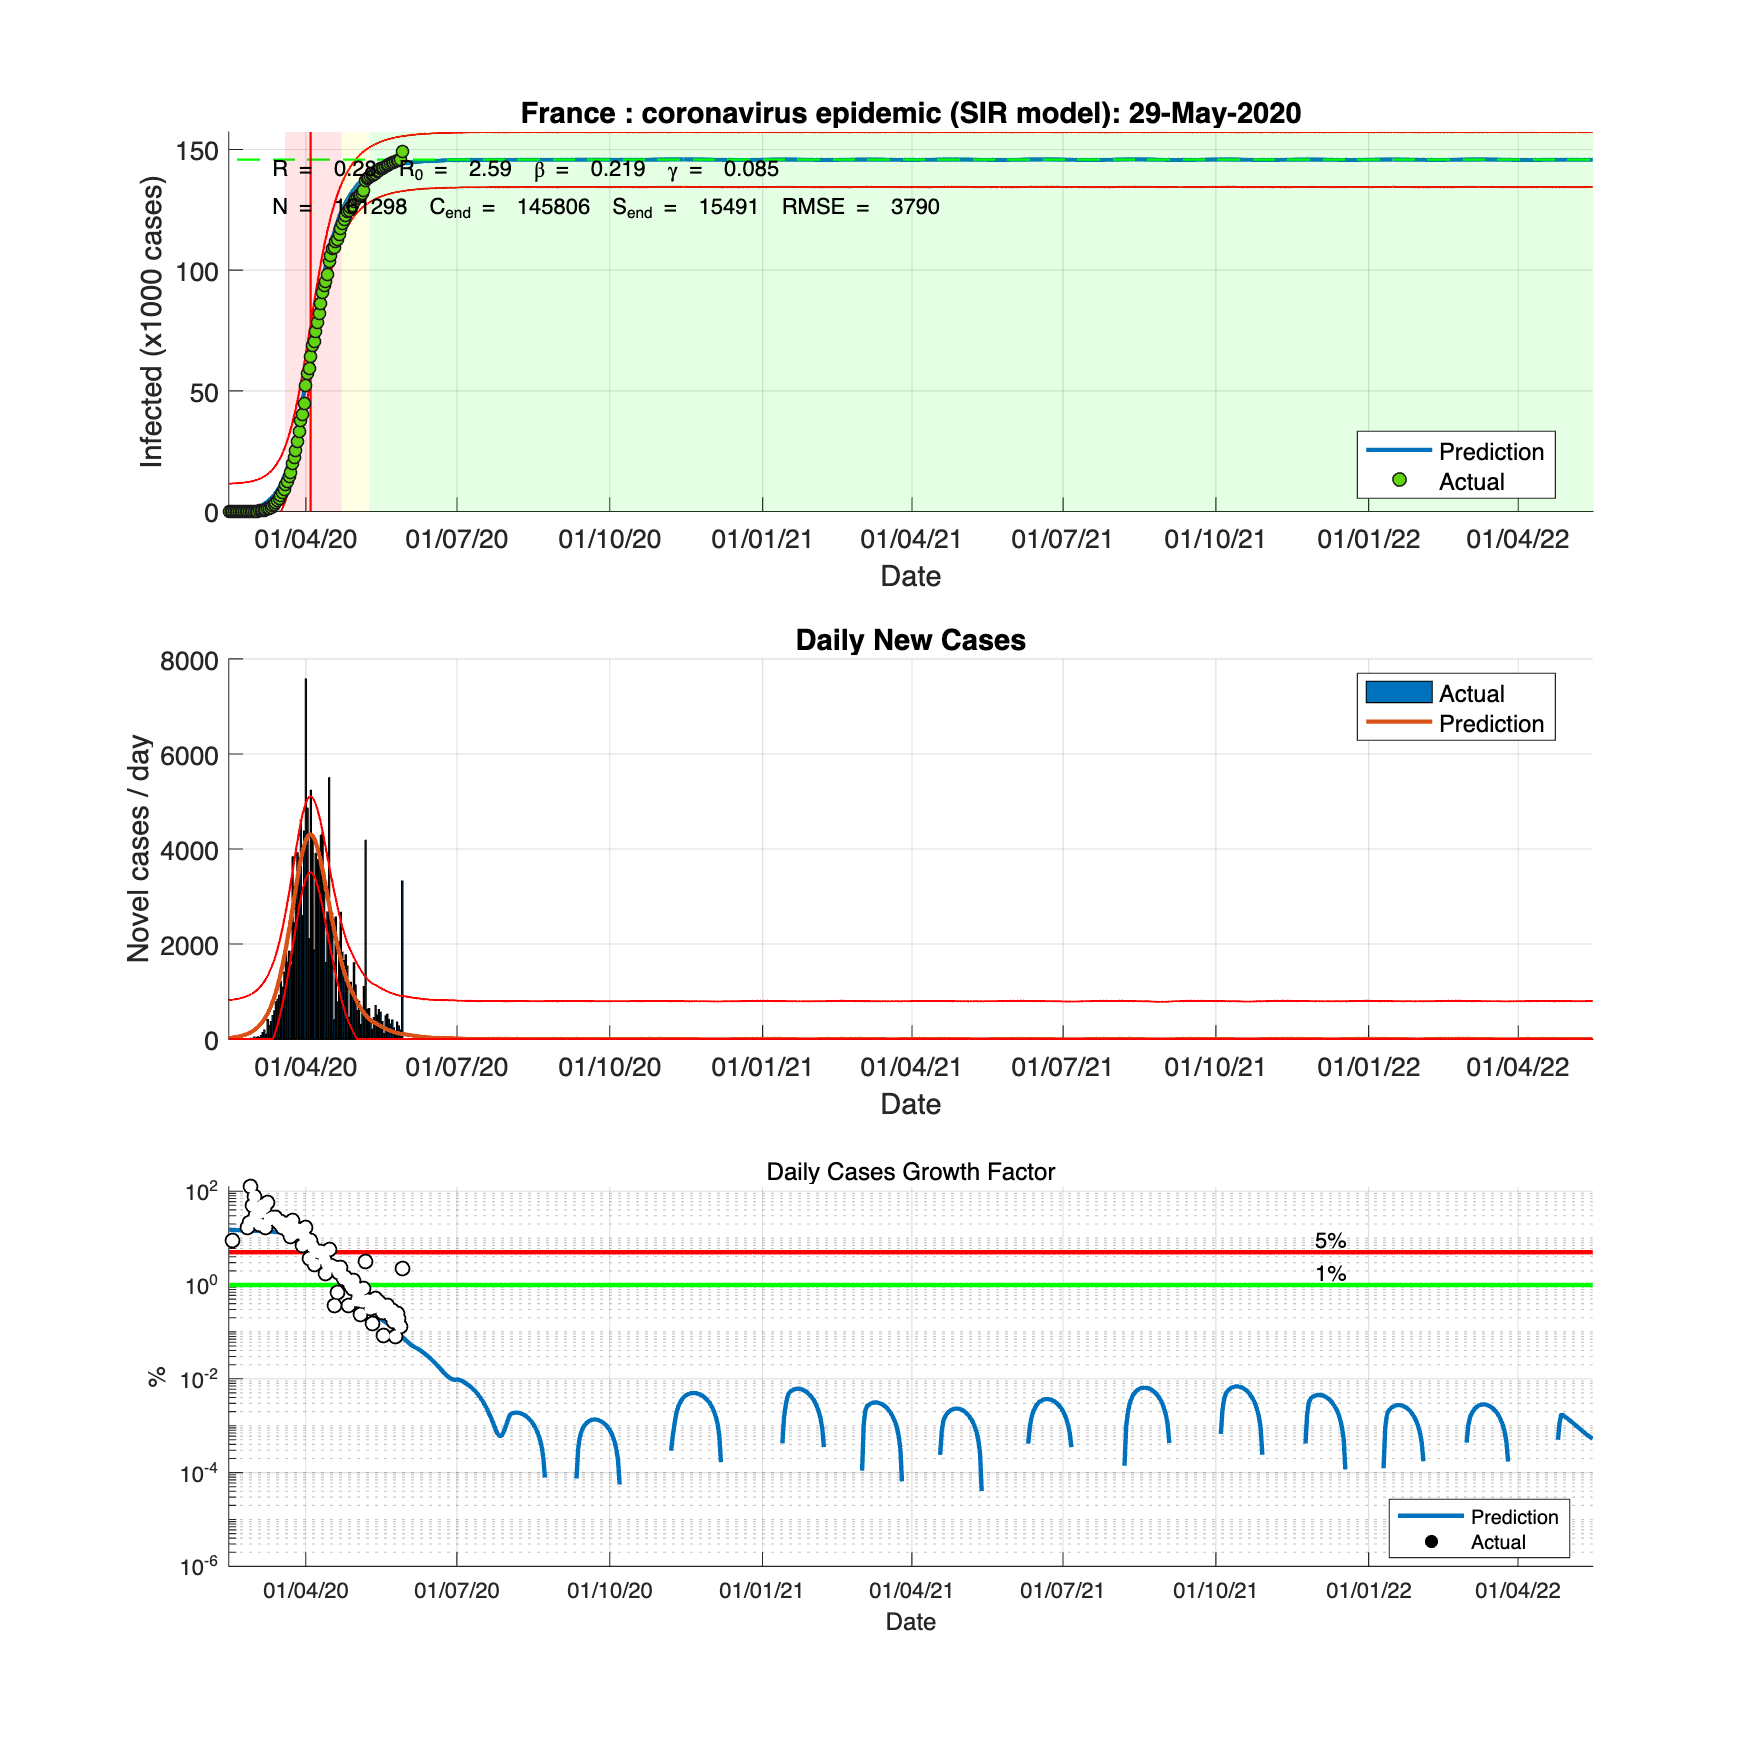

SA = SA.TagsGenerate( ...
    'TagContinuity', [0 1 1], ...
    'CustomTagName', {'centralization', [0 1 1]}, ...
    'CustomTagFunction', { ...
        'centralization', 'Centralized', @(x,y)(x{:,1}-tsnanmean(x{:,1}))/tsnanstd(x{:,1}); ...

        } ...
    );

/Users/maix00/Documents/MATLAB/MATLAB_Design_Course/Project/getDataTest.m


***Warning: not enaught data.
Fail to obtain initial approximation for China.


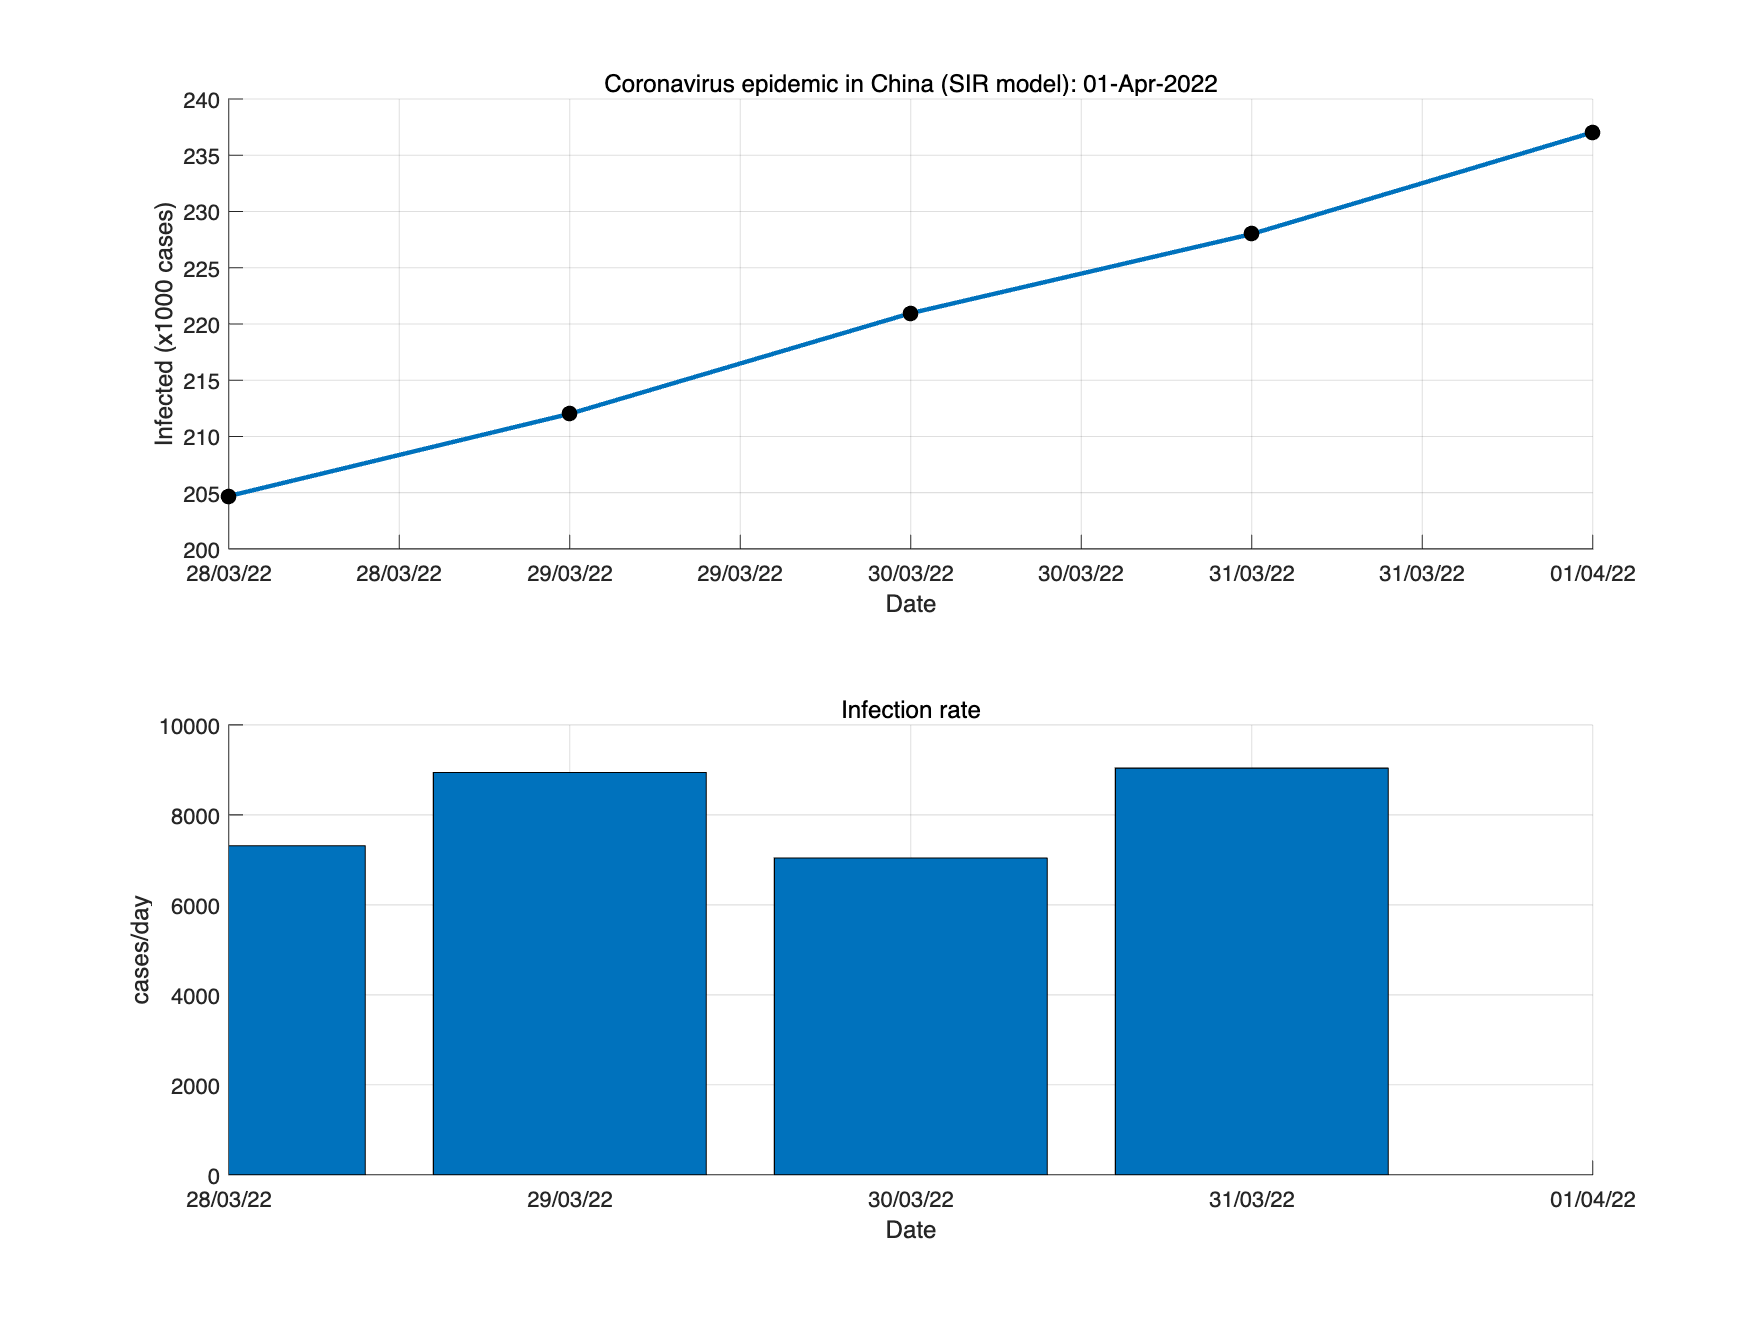

data = SA.addProp;

## 第三部分：数据处理

% SIR
myfitVirusCV19(@getDataFrance)

% SEIR
myfitVirusCV19(@getDataTest)